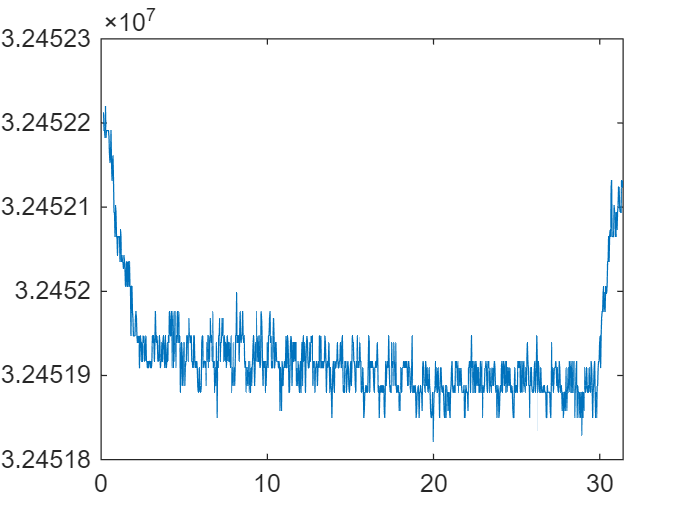

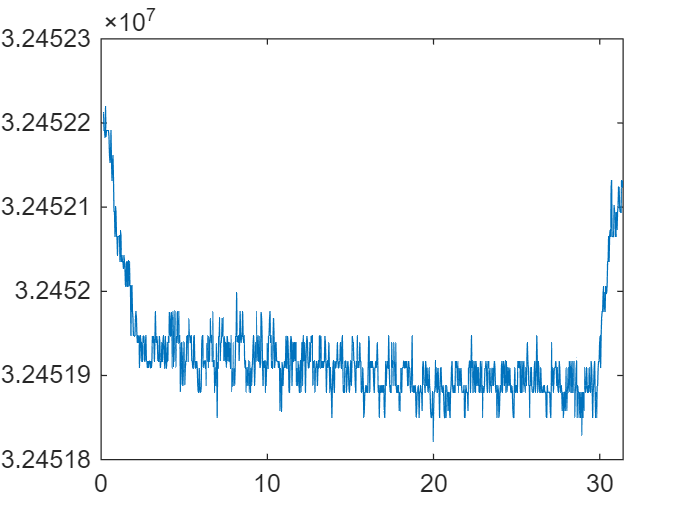

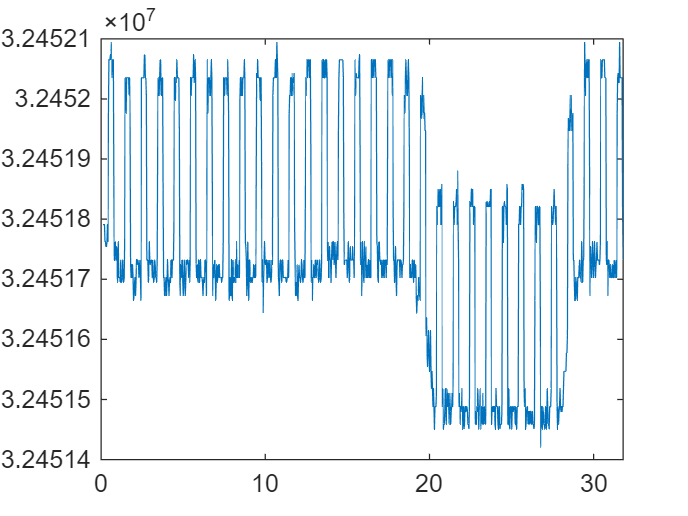

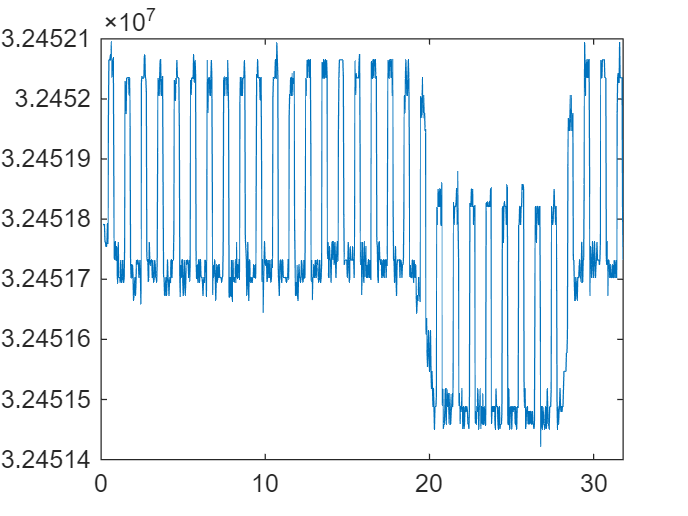

voltage = [0, 5.5];

data2plot = cell(1,length(voltage));

for i = 1:length(voltage)

filename = strcat('0050_20turn_F2_',num2str(voltage(i)),'V_1Hz.csv');

raw_data = readtable(filename,'Delimiter',',');

% Take care of header chunk
raw_time = raw_data{:,"Var1"};
[row, ~] = find(isnan(raw_time));

if ~isempty(row)
    % double check to make sure nan is from the header instead of data
    if (row(end) - row(1) + 1) == length(row)

        raw_data = raw_data(row(end)+1:end,:); % clip header
    end
end
raw_data(end,:) = [];   % get rid of last line in case of incomplete data log

% Raw time & data
time = raw_data{:,'Var1'}./1000; % in seconds
data = raw_data{:,'Var2'};

% Show raw data plot
figure;
plot(time, data)

time_difference = time(2:end) - time(1:end-1);
ts = mean(time_difference);
std_ts = std(time_difference);

fs = 1/ts;

rs_time = time(1):ts:time(end);

rs_data = interp1(time,data,rs_time,'spline');

figure;
plot(rs_time,rs_data)

clip_index = (rs_time > 5) & (rs_time < 25);
clip_time = rs_time(clip_index);
clip_data = rs_data(clip_index);

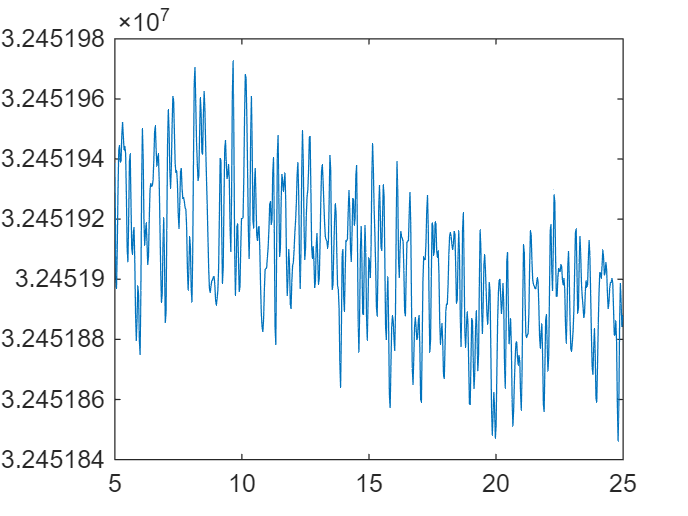

mean_data = 3.2452e+07

std_data = 23.6328

diff_data = 126.4946

rms_data = 23.6151

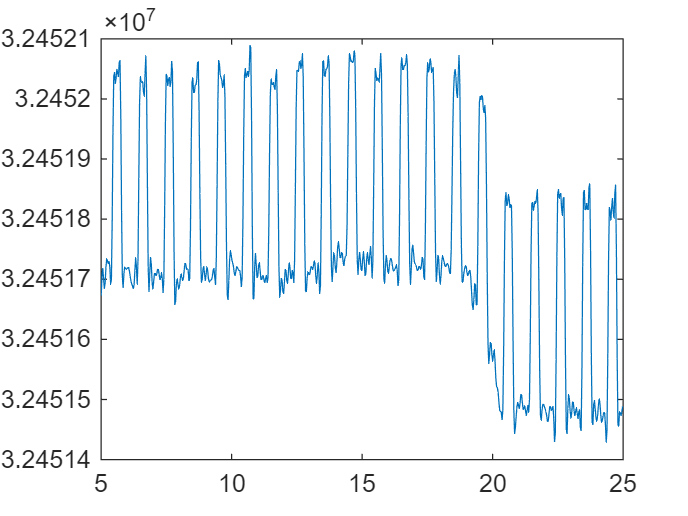

mean_data = 3.2452e+07

std_data = 178.9434

diff_data = 659.7696

rms_data = 178.8092


% Low pass to try to remove noise

cutoff_freq = 8;    % Cutoff frequency in Hz
filter_order = 4;    % Filter order (adjust as needed)

% lpf = designfilt('lowpassiir', ...
%     'FilterOrder', filter_order, ...
%     'HalfPowerFrequency', cutoff_freq, ...
%     'SampleRate', fs, ...
%     'DesignMethod', 'butter');

[b, a] = butter(filter_order, cutoff_freq/(fs/2), 'low');
lp_data= filtfilt(b, a, clip_data);

figure;
plot(clip_time, lp_data)

mean_data = mean(lp_data)
std_data = std(lp_data)
diff_data = max(lp_data) - min(lp_data)
rms_data = sqrt(mean((lp_data-mean_data).^2))

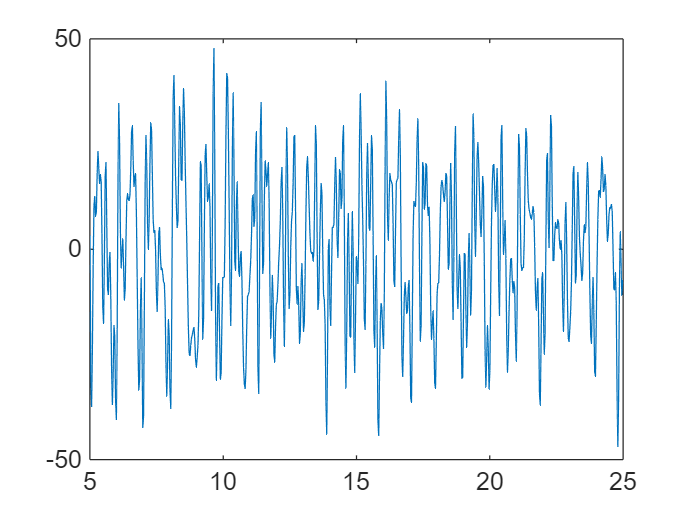

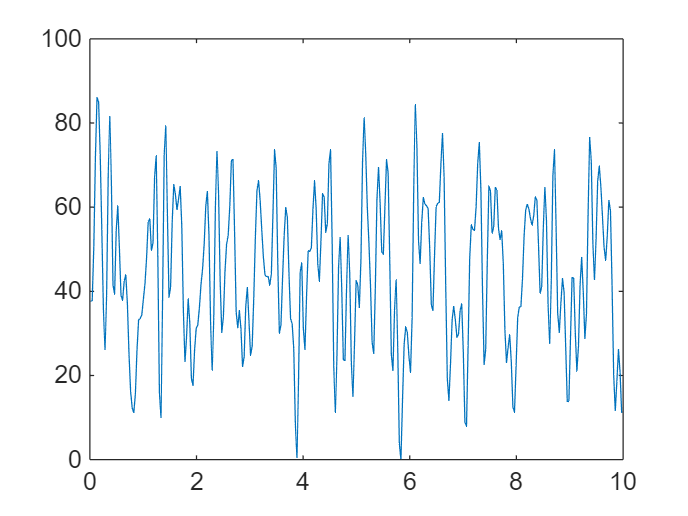

mean_data = 44.4681

std_data = 17.7233

diff_data = 86.0886

rms_data = 17.6967

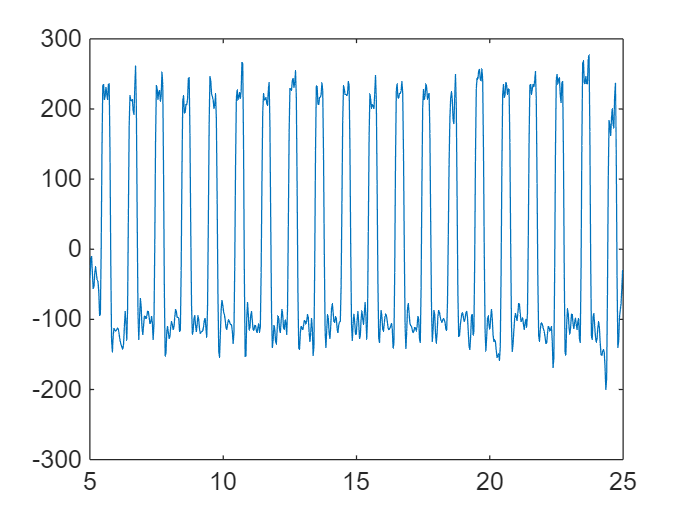

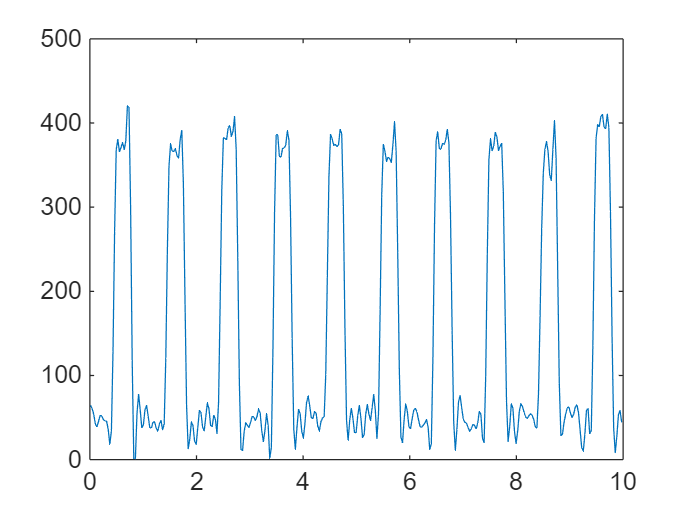

mean_data = 153.8889

std_data = 148.8291

diff_data = 420.1537

rms_data = 148.6055


% High pass to try to remove baseline

cutoff_freq = 0.5;    % Cutoff frequency in Hz
filter_order = 4;    % Filter order (adjust as needed)

% lpf = designfilt('lowpassiir', ...
%     'FilterOrder', filter_order, ...
%     'HalfPowerFrequency', cutoff_freq, ...
%     'SampleRate', fs, ...
%     'DesignMethod', 'butter');

[b, a] = butter(filter_order, cutoff_freq/(fs/2), 'high');
hp_data= filtfilt(b, a, lp_data);

figure;
plot(clip_time, hp_data)

final_idx = (clip_time > 10) & (clip_time < 20);
final_time = clip_time(final_idx);
final_data = hp_data(final_idx);

final_data = final_data - min(final_data);
final_time = final_time - 10;

figure;
plot(final_time, final_data)

data2plot{i} = [final_time;final_data]';

mean_data = mean(final_data)
std_data = std(final_data)
diff_data = max(final_data) - min(final_data)
rms_data = sqrt(mean((final_data-mean_data).^2))

end

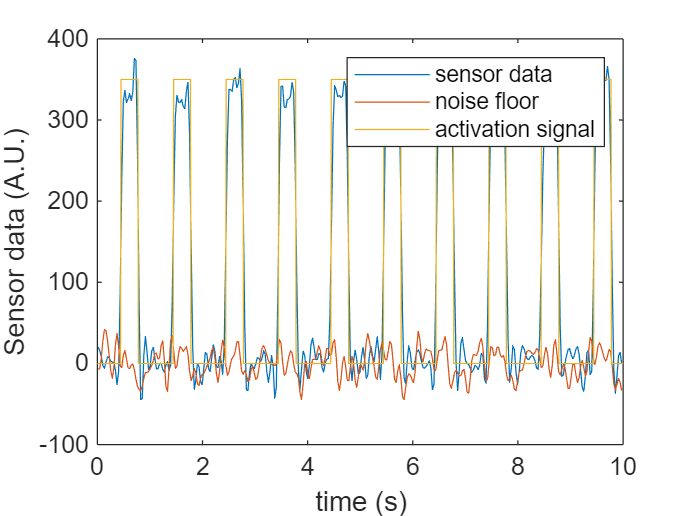

act_time = 8:0.01:22;
act_time(end) = [];
act_time = act_time - 10.22;
single_act_data = [zeros(1,67),ones(1,33)]*350;
act_data = repmat(single_act_data,1,14);

mean_line = mean(data2plot{1}(:,2));

figure;
plot(data2plot{2}(:,1),data2plot{2}(:,2)-mean_line);
hold on
plot(data2plot{1}(:,1),data2plot{1}(:,2)-mean_line);
plot(act_time,act_data);
hold off
xlim([0 10]);
ylabel('Sensor data (A.U.)')
xlabel('time (s)')
legend('sensor data','noise floor','activation signal')

plotted_data = data2plot{2}(:,2)-mean_line;

peak_data  = plotted_data(plotted_data > 280);
signal_floor = mean(peak_data)

signal_floor = 331.9030